# **Bridge of Doom - Danny Kennen and Oscar Bao**

## Paratetric Curve

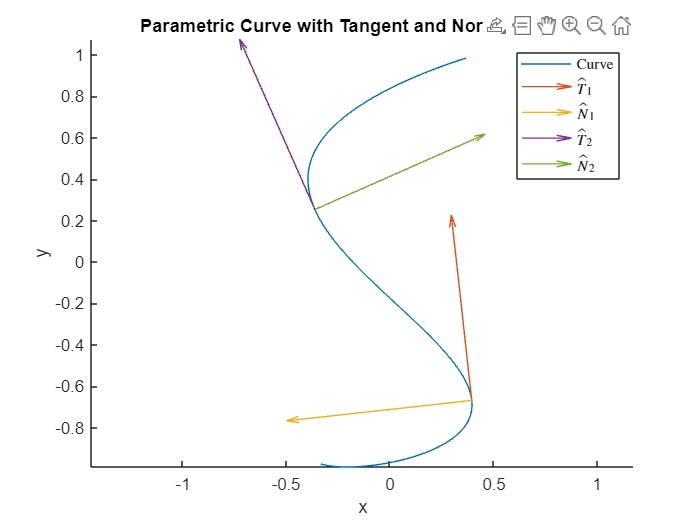

linspace_u = 0:0.01:3.2; %range given 
x = zeros(1, length(linspace_u));
y = zeros(1, length(linspace_u));
for i = 1:length(linspace_u)
    x(i) = .396*cos(2.65*(linspace_u(i)+1.4)); % 'x" side of the equation
    y(i) = -0.99*sin(linspace_u(i)+1.4); % "y" side of the equation 
end

%plotting the curve
clf
hold on
axis equal
plot(x,y, 'DisplayName', 'Curve');
xlabel('x')
ylabel('y')
title('Parametric Curve')
x_eq = .396*cos(2.65*(0.1*u+1.4));
y_eq = -0.99*sin(0.1*u+1.4);
r = [x_eq y_eq 0];
plotting_point = 10;
plotting_point2 = 20;

tangent_vec = diff(r)./norm(diff(r));
val_tangent = double(subs(tangent_vec, u, plotting_point));
val_tangent2 = double(subs(tangent_vec, u, plotting_point2));

normal_vec = diff(tangent_vec)./norm(diff(tangent_vec));

val_normal = double(subs(normal_vec, u, plotting_point));
val_og = double(subs(r, u, plotting_point));
val_normal2 = double(subs(normal_vec, u, plotting_point2));
val_og2 = double(subs(r, u, plotting_point2));

%Ploting the tangent and normal vectors on the curve 
axis equal
quiver(val_og(1), val_og(2), val_tangent(1), val_tangent(2), 'DisplayName', '$$\hat{T}_1$$')
quiver(val_og(1), val_og(2), val_normal(1), val_normal(2), 'DisplayName', '$$\hat{N}_1$$')
quiver(val_og2(1), val_og2(2), val_tangent2(1), val_tangent2(2), 'DisplayName', '$$\hat{T}_2$$')
quiver(val_og2(1), val_og2(2), val_normal2(1), val_normal2(2), 'DisplayName', '$$\hat{N}_2$$')
title('Parametric Curve with Tangent and Normal Vectors')
legend('Interpreter', 'latex')

syms u
clf
linspace_u = 0:0.1:32;
lin_velocity = zeros(1, length(linspace_u));
ang_velocity = zeros(1, length(linspace_u));
lin_vel_eq = norm(diff(r))

$$lin\_vel\_eq = \sqrt{\frac{27531009\,{\left|\sin\left(\frac{53\,u}{200}+\frac{371}{100}\right)\right|}^{2}}{2500000000}+\frac{9801\,{\left|\cos\left(\frac{u}{10}+\frac{7}{5}\right)\right|}^{2}}{1000000}}$$

ang_vel_eq = cross(tangent_vec, diff(tangent_vec))

$$ang\_vel\_eq = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & -\frac{99\,\sigma_{7}\,\left(\frac{278091\,\sigma_{3}}{10000000\,\sqrt{\sigma_{2}}}+\frac{5247\,\sigma_{6}\,\sigma_{1}}{100000\,{\sigma_{2}}^{3/2}}\right)}{1000\,\sqrt{\sigma_{2}}}-\frac{5247\,\sigma_{6}\,\left(\frac{99\,\sin\left(\frac{u}{10}+\frac{7}{5}\right)}{10000\,\sqrt{\sigma_{2}}}-\frac{99\,\sigma_{7}\,\sigma_{1}}{2000\,{\sigma_{2}}^{3/2}}\right)}{50000\,\sqrt{\sigma_{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{9801\,\left|\sigma_{7}\right|\,\left(\frac{\sin\left(\frac{\bar{u}}{10}+\frac{7}{5}\right)\,\sigma_{7}}{10}+\frac{\sin\left(\frac{u}{10}+\frac{7}{5}\right)\,\sigma_{4}}{10}\right)}{1000000\,\sqrt{\sigma_{7}\,\sigma_{4}}}-\frac{27531009\,\left|\sigma_{6}\right|\,\left(\frac{53\,\sin\left(\sigma_{5}\right)\,\sigma_{3}}{200}+\frac{53\,\sigma_{6}\,\cos\left(\sigma_{5}\right)}{200}\right)}{2500000000\,\sqrt{\sin\left(\sigma_{5}\right)\,\sigma_{6}}}\\ \sigma_{2}=\frac{27531009\,{\left|\sigma_{6}\right|}^{2}}{2500000000}+\frac{9801\,{\left|\sigma_{7}\right|}^{2}}{1000000}\\ \sigma_{3}=\cos\left(\frac{53\,u}{200}+\frac{371}{100}\right)\\ \sigma_{4}=\cos\left(\frac{\bar{u}}{10}+\frac{7}{5}\right)\\ \sigma_{5}=\frac{53\,\bar{u}}{200}+\frac{371}{100}\\ \sigma_{6}=\sin\left(\frac{53\,u}{200}+\frac{371}{100}\right)\\ \sigma_{7}=\cos\left(\frac{u}{10}+\frac{7}{5}\right) \end{array}$$

for i = 1:length(linspace_u)
    lin_velocity(i) = subs(lin_vel_eq, u, linspace_u(i));
    temp = subs(ang_vel_eq, u, linspace_u(i));
    ang_velocity(i) = temp(3);
end

## Linear and Angular Velocity

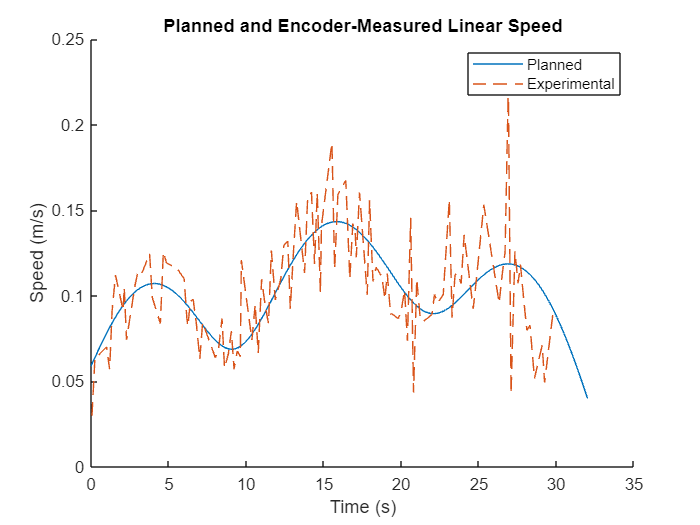

% plotting linear velocity over time
figure;
hold on
plot(linspace_u, lin_velocity, 'DisplayName', 'Planned')
plot(encoder_data(1:length(real_linear_speed),1), real_linear_speed, '--', 'DisplayName', 'Experimental')
title('Planned and Encoder-Measured Linear Speed')
xlabel('Time (s)')
ylabel('Speed (m/s)')
legend()

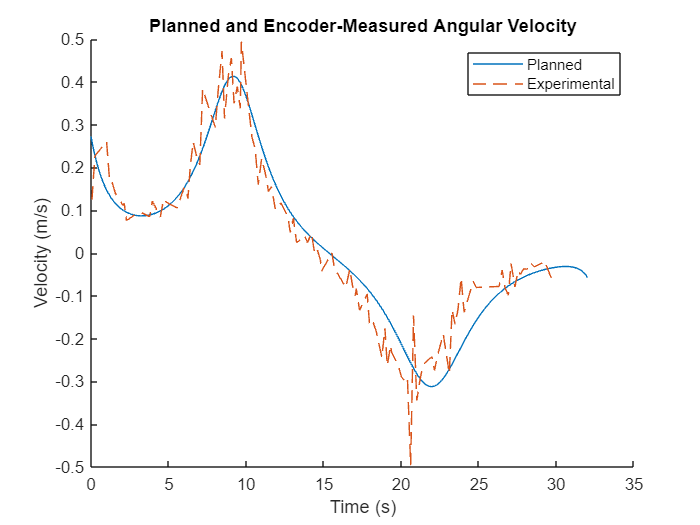

%plotting angular velocity over time
figure
hold on
plot(linspace_u, ang_velocity,'DisplayName', 'Planned')
plot(encoder_data(1:length(real_linear_speed),1), real_angular_velocity,'--','DisplayName','Experimental')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
title('Planned and Encoder-Measured Angular Velocity')
legend()

## Wheel Velocity 

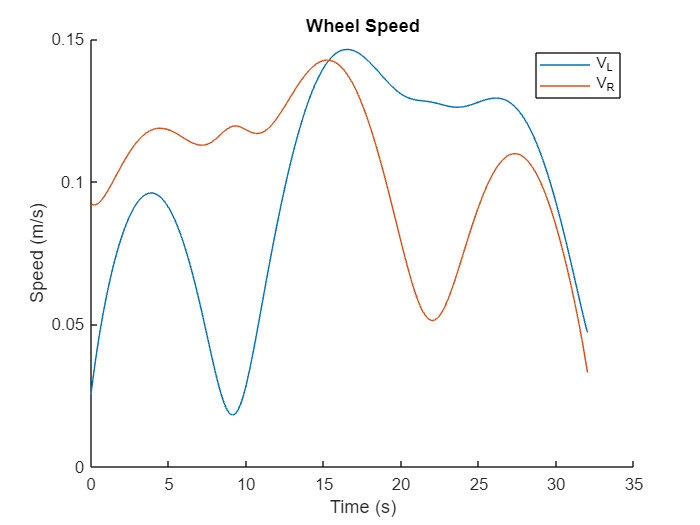

left_wheel_vel = zeros(1, length(linspace_u));
right_wheel_vel = zeros(1, length(linspace_u));

left_vel_eq = lin_vel_eq - 0.124*ang_vel_eq; %Left velocity equation 
right_vel_eq = lin_vel_eq + 0.124*ang_vel_eq; %Right velocity eqation 

double(subs(left_vel_eq, u, 11)); %turns the equation into useable numbers
for i = 1:length(linspace_u) % This loop gets the velocity for each moment of u
    left_wheel_vel(i) = lin_velocity(i) - ang_velocity(i)*0.1225;
    right_wheel_vel(i) = lin_velocity(i) + ang_velocity(i)*0.1225;
end

% Plot the velocities
clf
hold on
plot(linspace_u, left_wheel_vel, 'DisplayName', '{V_L}')
plot(linspace_u, right_wheel_vel, 'DisplayName', '{V_R}')
title('Wheel Speed')
xlabel('Time (s)')
ylabel('Speed (m/s)')
legend()

## Plotting Robot path

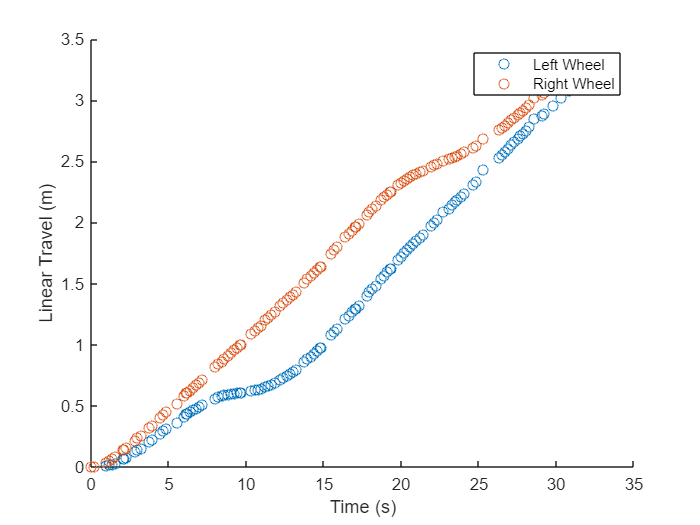

%Plot how the wheels travel over time
clf
hold on
scatter(encoder_data(:,1), encoder_data(:,2), 'DisplayName', 'Left Wheel')
scatter(encoder_data(:,1), encoder_data(:,3), 'DisplayName', 'Right Wheel')
legend()
xlabel("Time (s)")
ylabel("Linear Travel (m)")

encoder_data = encoder_data_og(1:179,1:3);
i = 2;
% This while loop makes it that if distance between the wheels is the same as the distance at the last time stamp 
% it will kick out the distance at the last time step do the velocity does not equal zero
while i <= size(encoder_data, 1) 
    if encoder_data(i,2:3) == encoder_data(i-1,2:3)
        encoder_data(i-1,:) = [];
    end
    i = i + 1;
end
encoder_vel_left = diff(encoder_data(:,2))./diff(encoder_data(:,1));
encoder_vel_right = diff(encoder_data(:,3))./diff(encoder_data(:,1));

encoder_vel_left = encoder_vel_left(~any(encoder_vel_left == 0, 2), :);
encoder_vel_right = encoder_vel_right(~any(encoder_vel_right == 0, 2), :);

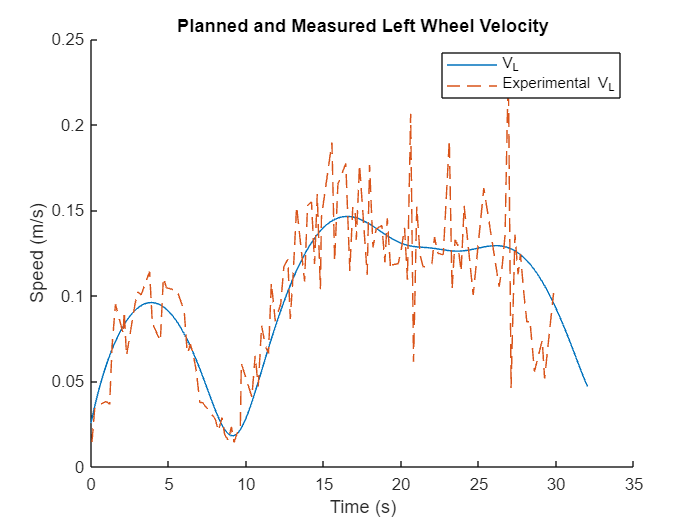

% Plots the encoder data against the calculated velocity of the left wheel
% over time
clf
figure
hold on
plot(linspace_u, left_wheel_vel, 'DisplayName', '{V_L}')
plot(encoder_data(1:length(encoder_vel_left),1), encoder_vel_left,'--', 'DisplayName', 'Experimental {V_L}')
title('Planned and Measured Left Wheel Velocity')
xlabel('Time (s)')
ylabel('Speed (m/s)')
legend()
hold off

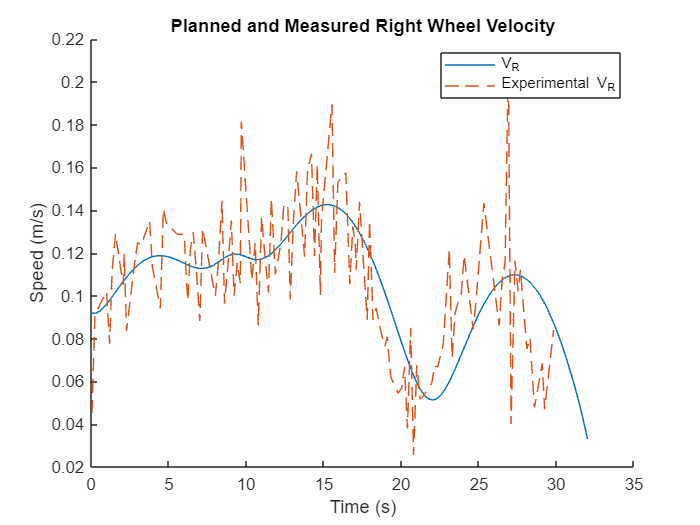

% Plots the encoder data against the calculated velocity of the right wheel
% over time
figure
hold on
plot(linspace_u, right_wheel_vel, 'DisplayName', '{V_R}')
plot(encoder_data(1:length(encoder_vel_right),1), encoder_vel_right, '--','DisplayName', 'Experimental {V_R}')
title('Planned and Measured Right Wheel Velocity')
xlabel('Time (s)')
ylabel('Speed (m/s)')
legend()
hold off

## Methodology 

Tangent Vector equation = $T$$=\frac{\frac{\mathrm{d}}{\mathrm{d}r}r}{\left\|\frac{\mathrm{d}}{\mathrm{d}r}r\right\|}$ 

Left Wheel Velocity $V_L =\left\|\frac{\mathrm{d}}{\mathrm{d}r}r\right\|$- $\left(T\;X\;\frac{\mathrm{d}}{\mathrm{d}T}T\right)$$*d$ 

Right Wheel Velocity $V_R =\left\|\frac{\mathrm{d}}{\mathrm{d}r}r\right\|$+ $\left(T\;X\;\frac{\mathrm{d}}{\mathrm{d}T}T\right)$$*d$

1) generate a set of left and right wheel velocity commands from a given parametric equation, and 2) reconstruct a path from encoder data. This description should include relevant equations. The focus of this section should be on the theoretical aspects of the path planning and mapping, not on the implementation in Matlab.

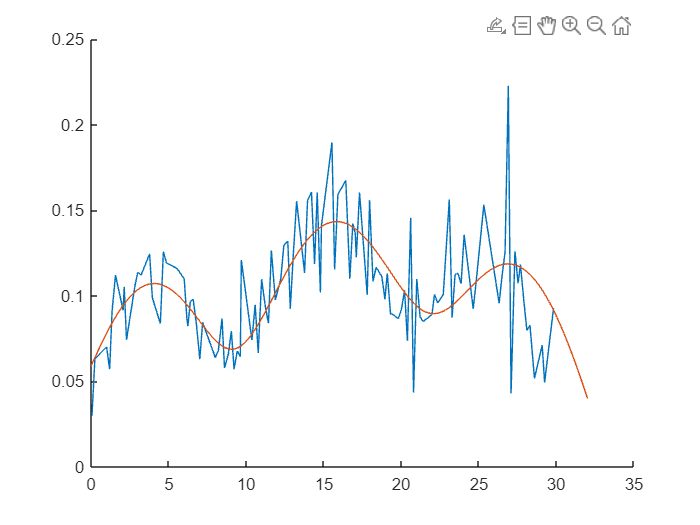

real_linear_speed = (encoder_vel_left + encoder_vel_right) ./ 2;
real_angular_velocity = (encoder_vel_right - encoder_vel_left) ./ 0.245;

clf
hold on
plot(encoder_data(1:length(real_linear_speed),1), real_linear_speed)
plot(linspace_u, lin_velocity, 'DisplayName', 'Linear Speed')
hold off

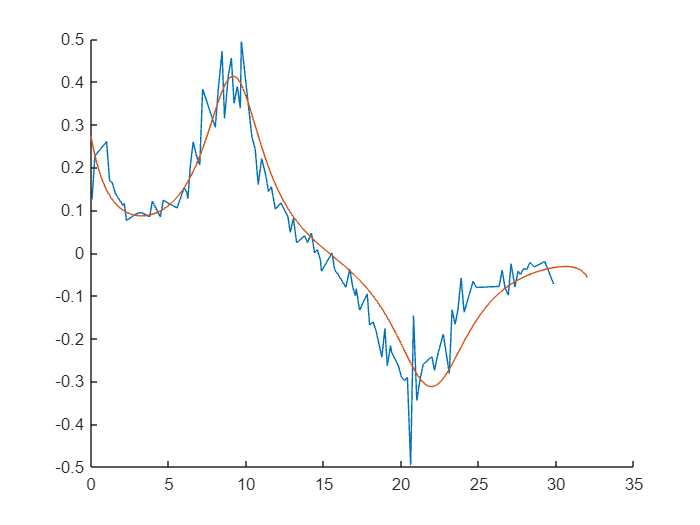

figure
hold on
plot(encoder_data(1:length(real_linear_speed),1), real_angular_velocity)
plot(linspace_u, ang_velocity,'DisplayName', 'Angular Velocity')
hold off

clf


real_heading = zeros(1, length(real_angular_velocity)+1);
real_heading(1) = -ang_velocity(1);
real_position = zeros(length(real_angular_velocity)+1, 2);
real_position(1,:) = [x(1), y(1)];

for i = 2:length(real_heading)
    real_heading(i) = real_heading(i-1) + real_angular_velocity(i-1).*(encoder_data(i,1)-encoder_data(i-1,1));
    position_change = [real_linear_speed(i-1).*cos(real_heading(i-1)).*(encoder_data(i,1)-encoder_data(i-1,1)),...
        real_linear_speed(i-1).*sin(real_heading(i-1)).*(encoder_data(i,1)-encoder_data(i-1,1))];
    real_position(i,:) = real_position(i-1,:) + position_change;
end

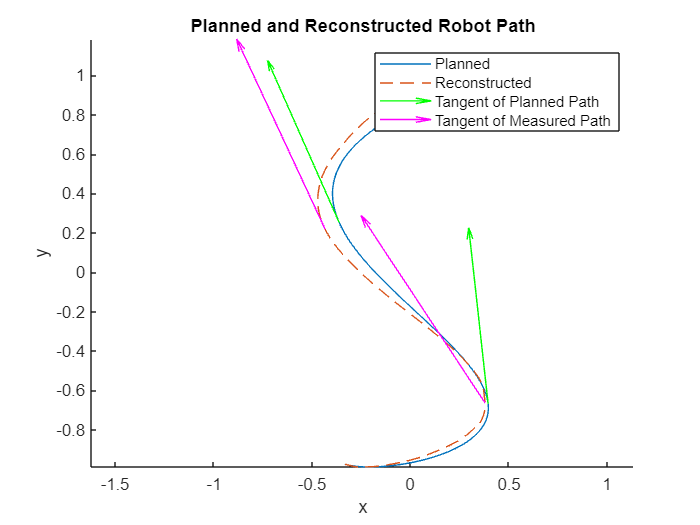

%plotting the path with the encoder data
real_tangent_slope = diff(real_position(:,2))./diff(real_position(:,1));
distances1 = sqrt(sum((real_position - val_og(1:2)).^2, 2));
[~, index1] = min(distances1);
closest1 = real_position(index1, :);
distances2 = sqrt(sum((real_position - val_og2(1:2)).^2, 2));
[~, index2] = min(distances2);
closest2 = real_position(index2, :);

clf
hold on
plot(x,y, 'DisplayName', 'Planned');
plot(real_position(:,1), real_position(:,2), '--','DisplayName', 'Reconstructed')

quiver(val_og(1), val_og(2), val_tangent(1), val_tangent(2), 'g', 'DisplayName', 'Tangent of Planned Path')
quiver(val_og2(1), val_og2(2), val_tangent2(1), val_tangent2(2), 'g')
quiver(closest1(1), closest1(2), -0.7, -0.1*real_tangent_slope(index1), 'm')
quiver(closest2(1), closest2(2), -0.5, -0.5*real_tangent_slope(index2), 'm')

title('Planned and Reconstructed Robot Path')
xlabel('x')
ylabel('y')
axis equal
legend('Planned', 'Reconstructed', 'Tangent of Planned Path', '', '', 'Tangent of Measured Path')